two=load('TwoAnimals.mat');
single=load('SingleAnimal.mat');
three=load('ThreeAnimals.mat');
annotKp3ds=cat(3,reshape(three.annotKp3ds,18,3,[]),...
                reshape(two.annotKp3ds,18,3,[]),...
                 squeeze(single.annotKp3ds));
decodedKp3ds=cat(3,reshape(three.decodedKp3ds,18,3,[]),...
                   reshape(two.decodedKp3ds,18,3,[]),...
                   squeeze(single.decodedKp3ds));

gapdata=squeeze(vecnorm((annotKp3ds-decodedKp3ds),2,2));

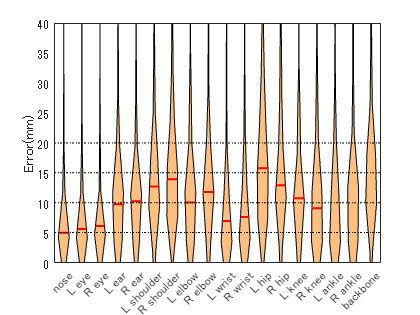

flgValid=nanmedian(gapdata)<10000000000000000000000000000;

figure; 
[h, L, MX, MED, bw]=violin(gapdata(:,flgValid)','mc',[]);ylim([0 40]);
kp_names = {'nose', 'L eye', 'R eye', 'L ear', 'R ear',...
            'L shoulder', 'R shoulder', 'L elbow', 'R elbow', 'L wrist', 'R wrist',...
            'L hip', 'R hip', 'L knee', 'R knee', 'L ankle', 'R ankle', 'backbone'};
set(gca,'xtick',[1:18],'xticklabels',kp_names);
L.Visible='off';
% view([90,90]);
view([0,90]);
plot([0 19],[5 5],':k');
plot([0 19],[10 10],':k');
plot([0 19],[15 15],':k');
plot([0 19],[20 20],':k');
ylabel('Error(mm)');